# 1229上课内容(2)

## Matlab图像处理

## 表达方式

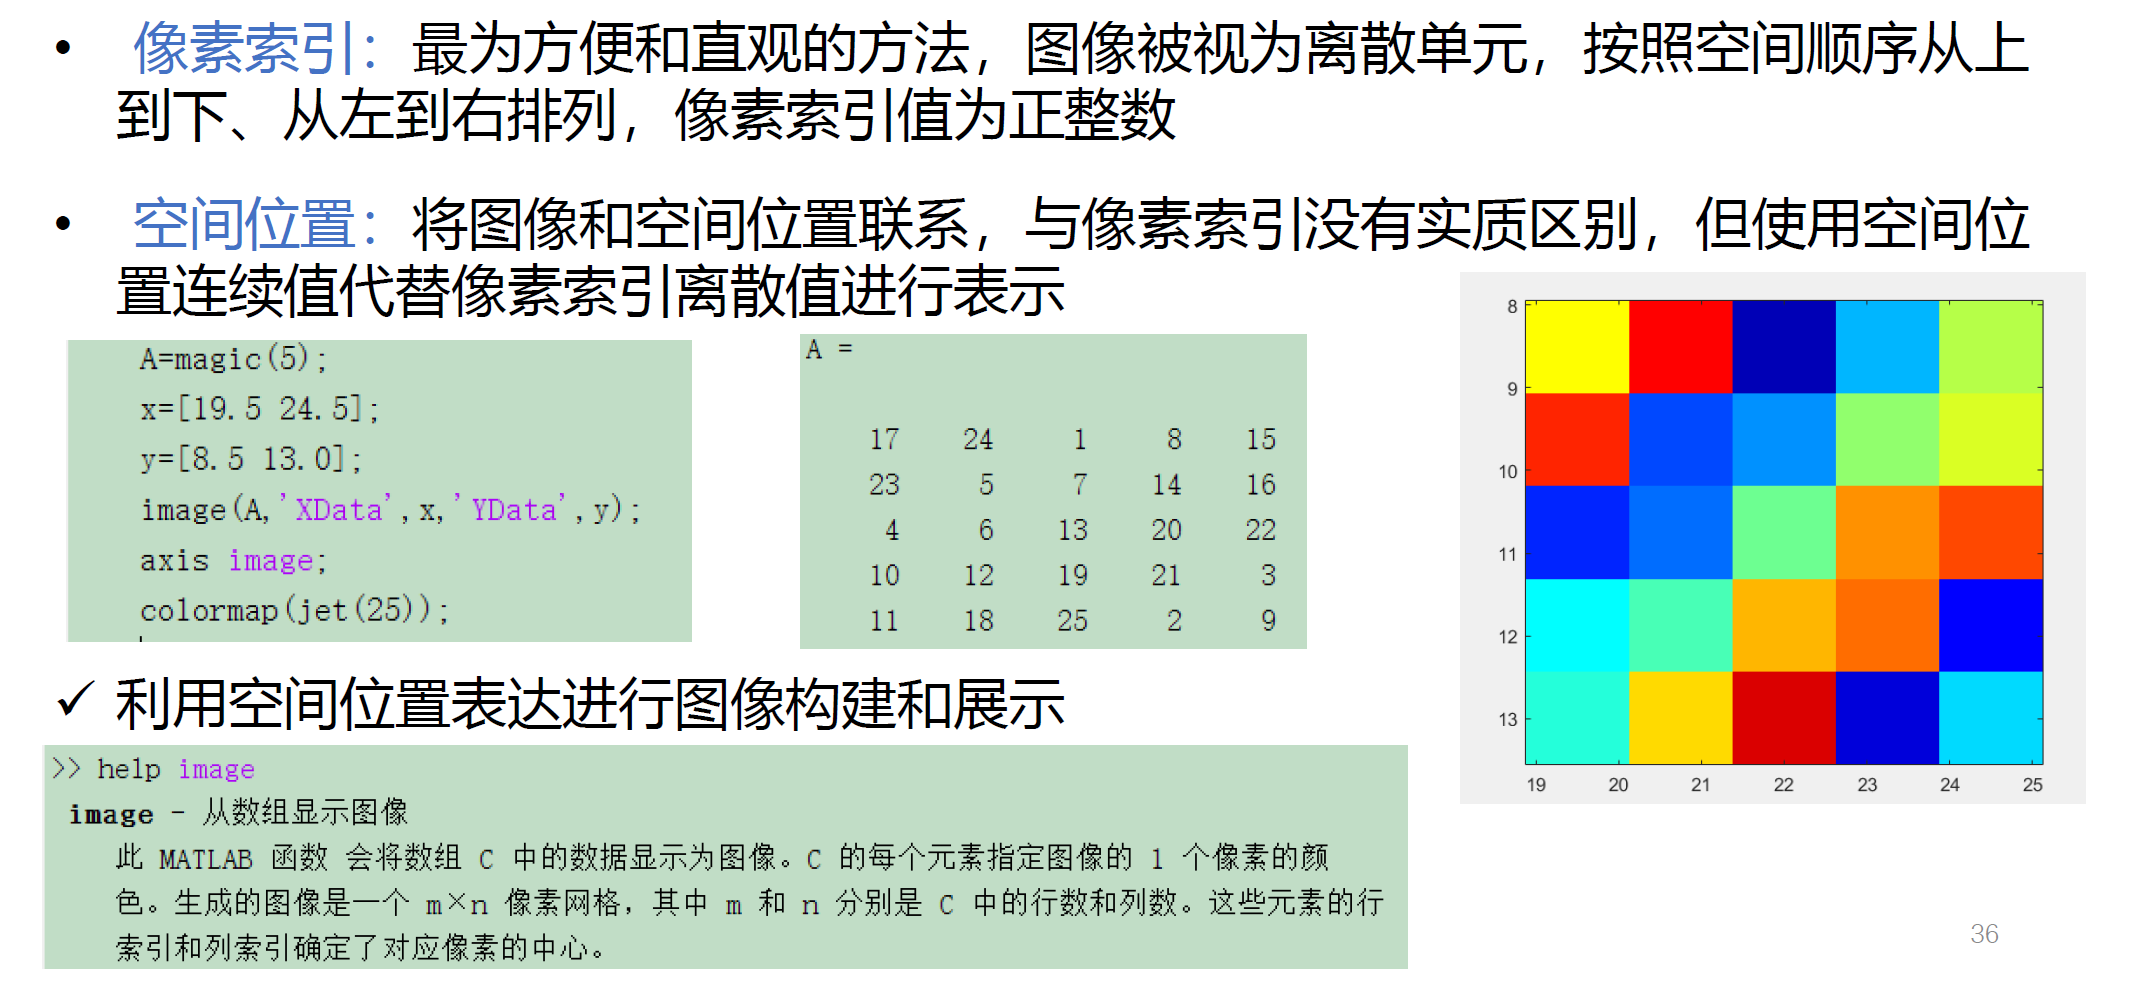

## 图像的存储方式

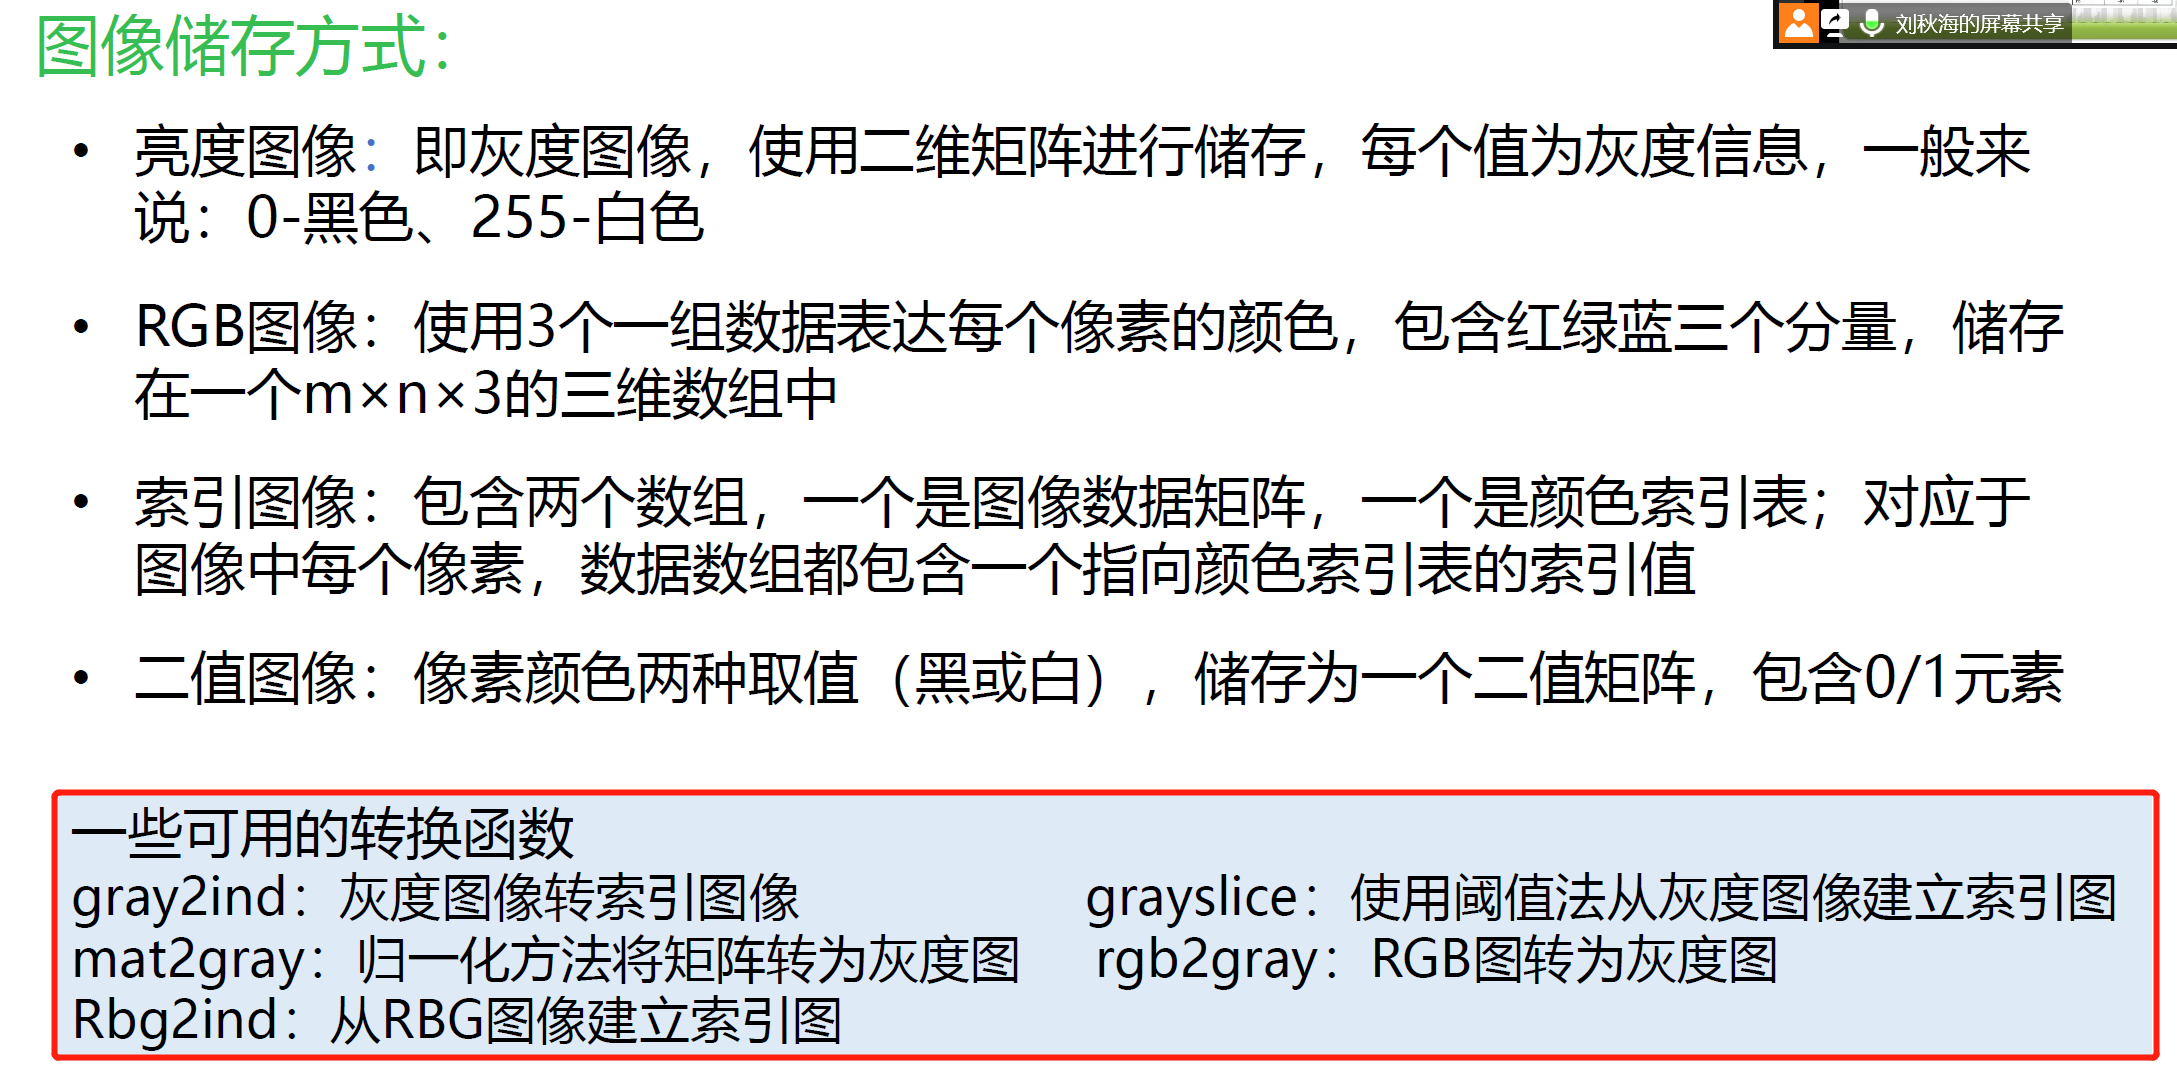

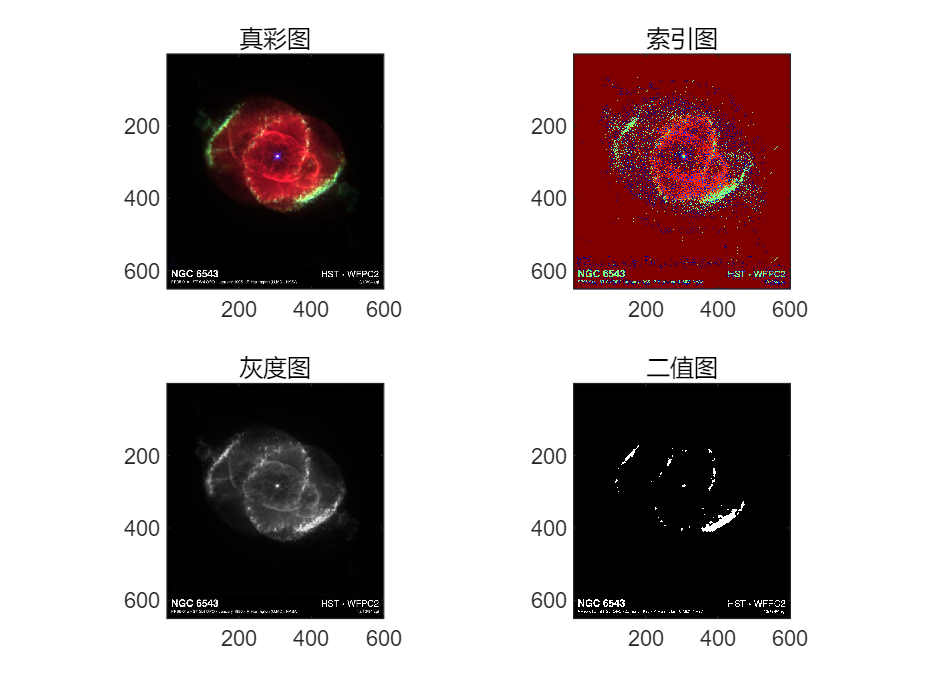

close all;
% 真彩图像转换为索引图像
RGB = imread('ngc6543a.jpg'); % 内置图像
map = jet(256);
X = dither(RGB,map);
subplot(2,2,1);subimage(RGB);
title('真彩图');
subplot(2,2,2);subimage(X,map);
title('索引图');
% 彩色图转换为灰度图
I = rgb2gray(RGB);
subplot(2,2,3);subimage(I);
title('灰度图');
% 彩色图转换为二值图像
BW = im2bw(RGB,0.5);
subplot(2,2,4);subimage(BW);
title("二值图");

## 图像的显示

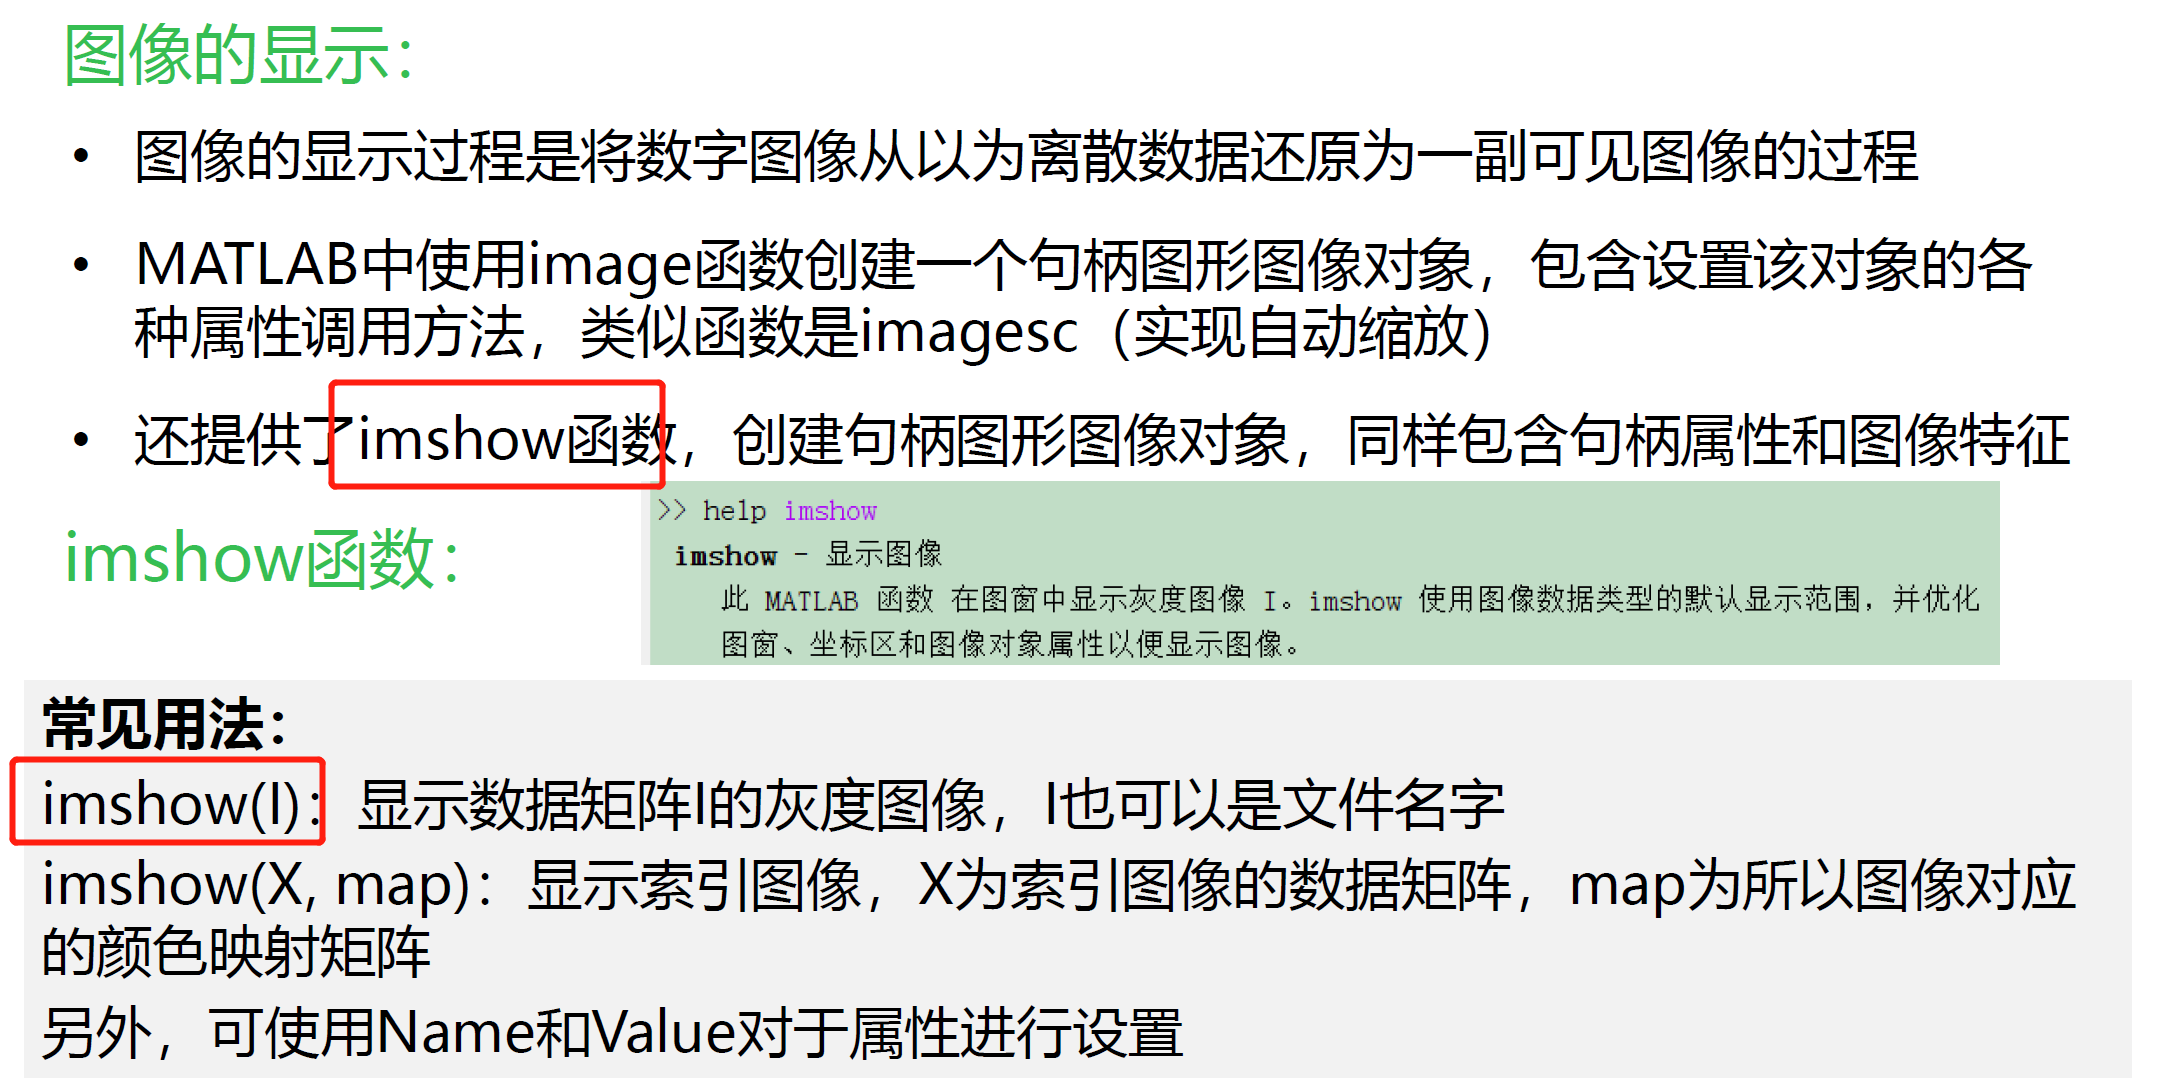

I = imread('lena.bmp');

错误使用 imread>get_full_filename
文件 "lena.bmp" 不存在。

出错 imread (第 371 行)
    fullname = get_full_filename(filename);

figure;
subplot(1,2,1);imshow(I);
% 采用默认的灰度级显示灰度图像
subplot(1,2,2);imshow(I,[60,120]);
% 设置灰度上下为[60,120]显示灰度图像

## image和imagesc函数

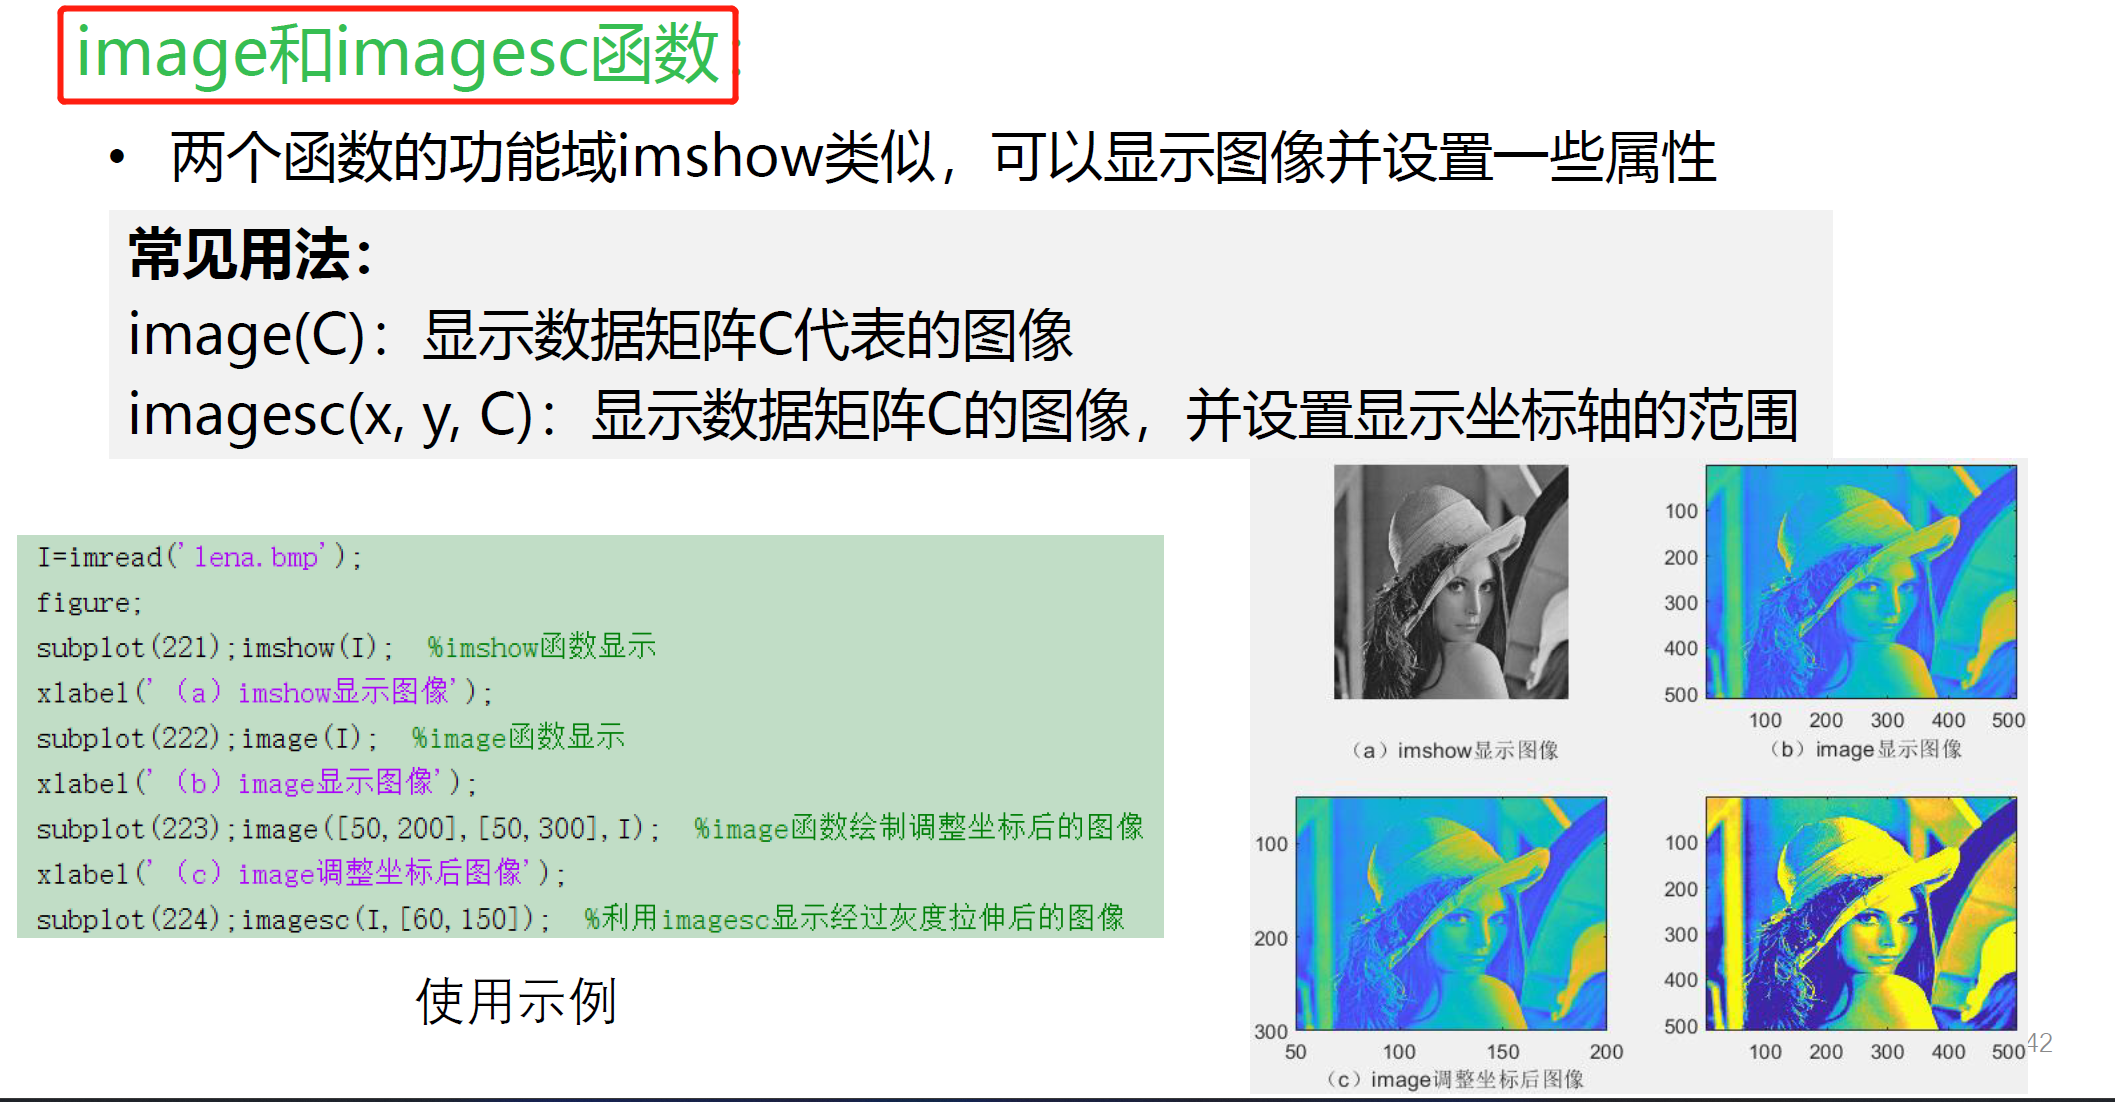

## colorbar 

**添加一个彩色条，用来指示图像中不同颜色所对应的具体数值**

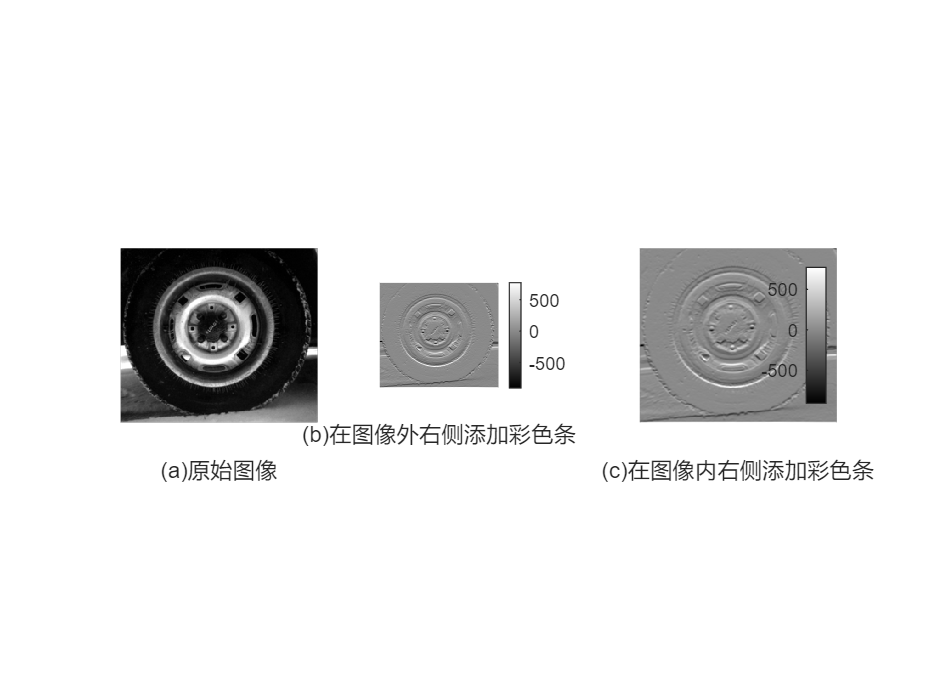

close all;
I = imread('tire.tif'); 
H = [1,2,1;0,0,0;-1,-2,-1]; % 设置sobel算子
X = filter2(H,I); % 对灰度图像I进行2次滤波，实现边缘检测
subplot(1,3,1);imshow(I); % 原始图像
xlabel('(a)原始图像');
subplot(1,3,2);imshow(X,[]);
colorbar; % 默认位置
xlabel('(b)在图像外右侧添加彩色条');
subplot(1,3,3);imshow(X,[]);
colorbar('east'); % 在图像内右侧添加彩色条
xlabel('(c)在图像内右侧添加彩色条');

% 设置sobel算子进行边缘检测
% 添加了对于图片中颜色值展示colorbar

## subimage函数

**将多个图像显示一个图形窗口中，方便进行比较和查看**

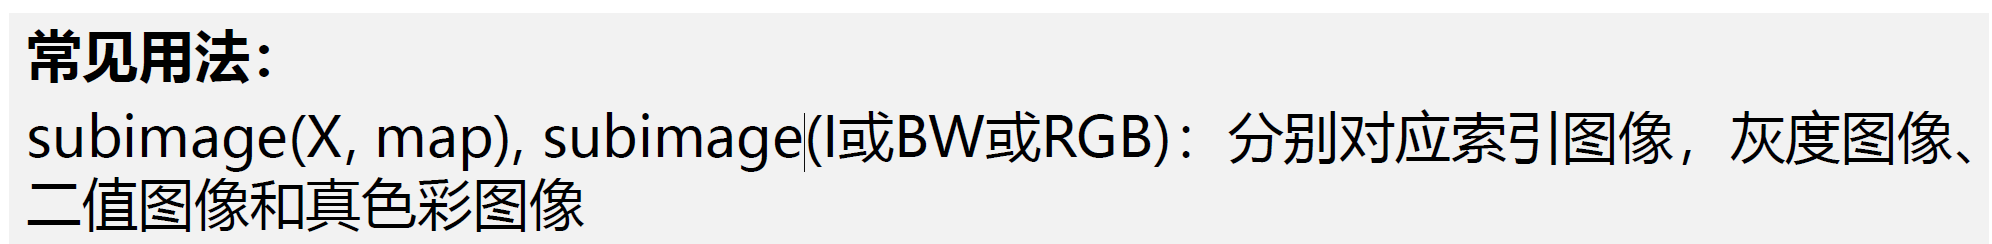

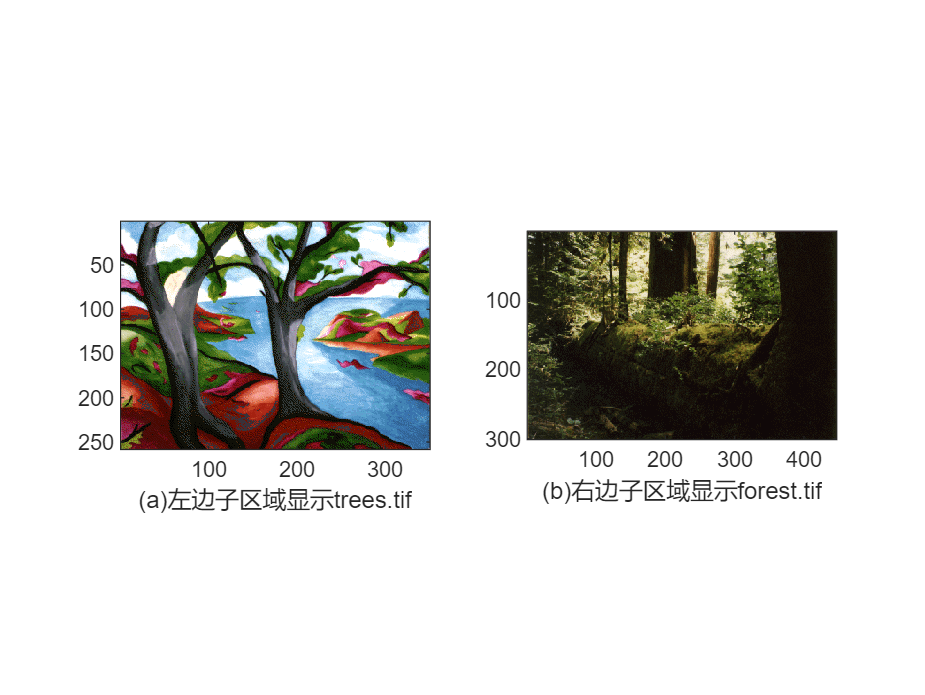

close all;
load trees;
[X2,map2] = imread('forest.tif');
subplot(1,2,1);subimage(X,map);
xlabel('(a)左边子区域显示trees.tif');
subplot(1,2,2);subimage(X2,map2);
xlabel('(b)右边子区域显示forest.tif');

## 图像的运算

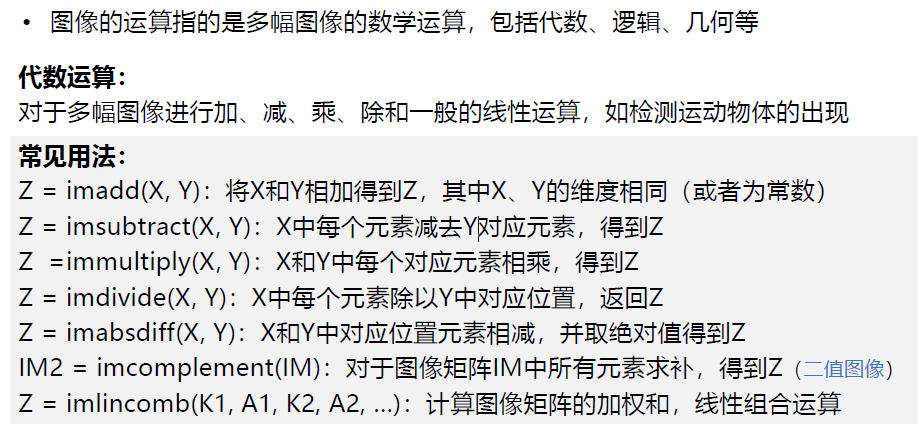

**图像的运算例子**

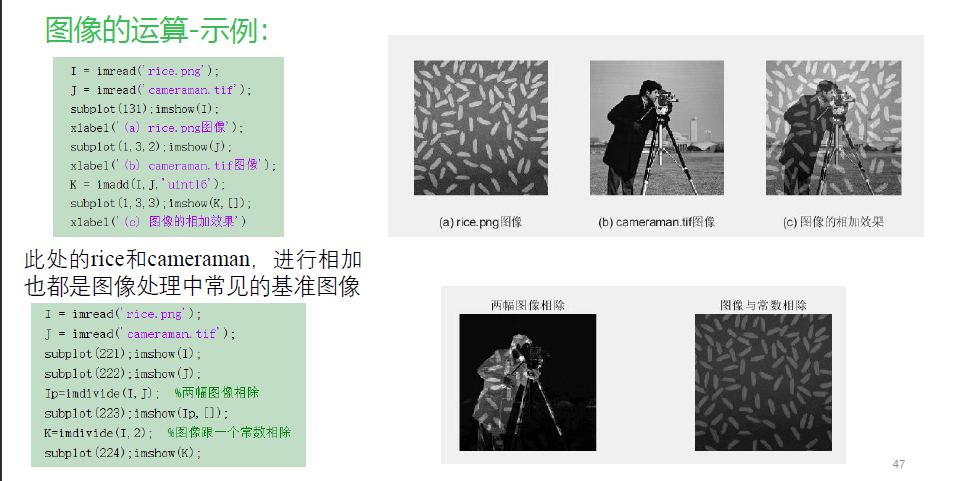

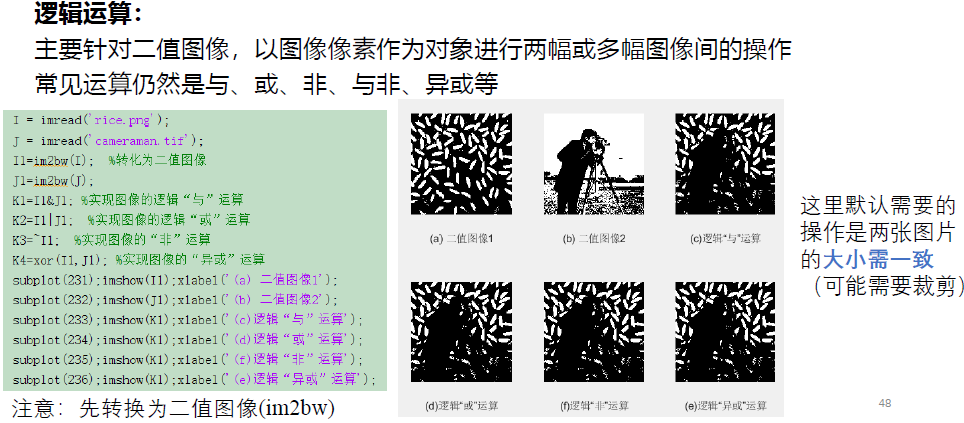

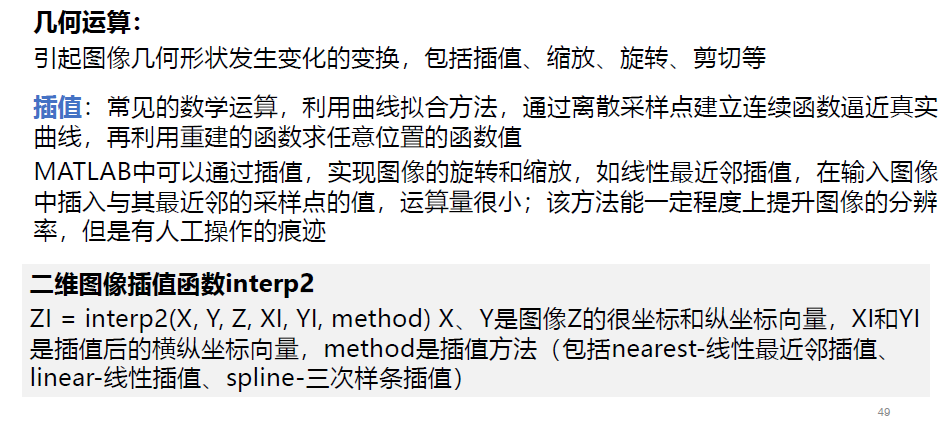

**其余运算可以查ppt**

## 图像处理

### 傅里叶变换

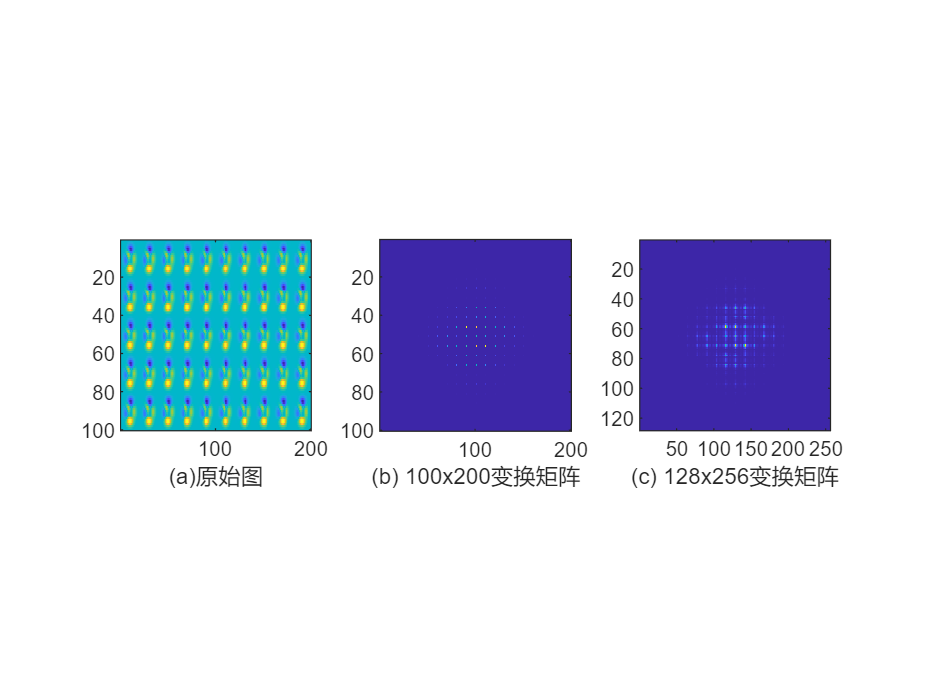

close all;
P = peaks(20);
X = repmat(P,[5,10]);
subplot(1,3,1);imagesc(X);axis square;
xlabel('(a)原始图');
Y = fft2(X); % 傅里叶频率平移后得到的结果
subplot(1,3,2);imagesc(abs(fftshift(Y)));axis square;
xlabel('(b) 100x200变换矩阵');
Y = fft2(X,2^nextpow2(100),2^nextpow2(200)); % 傅里叶频率平移后得到的结果
subplot(1,3,3);imagesc(abs(fftshift(Y)));axis square;
xlabel('(c) 128x256变换矩阵');

### 图像增强示例

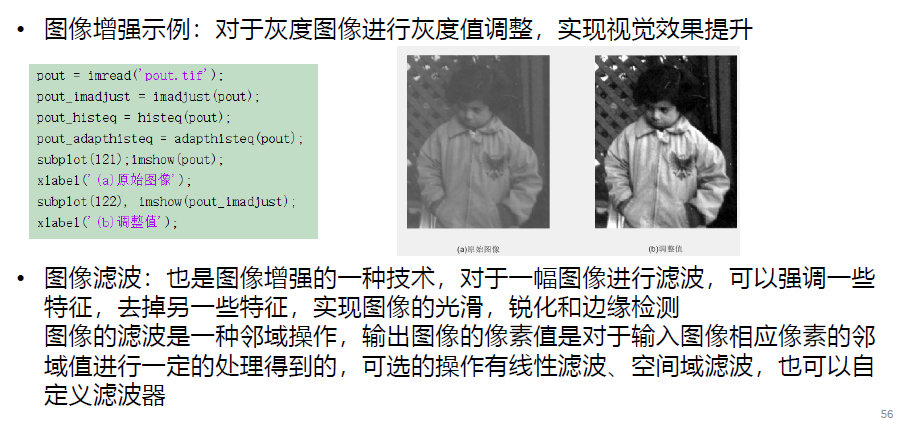

### 图像滤波示例

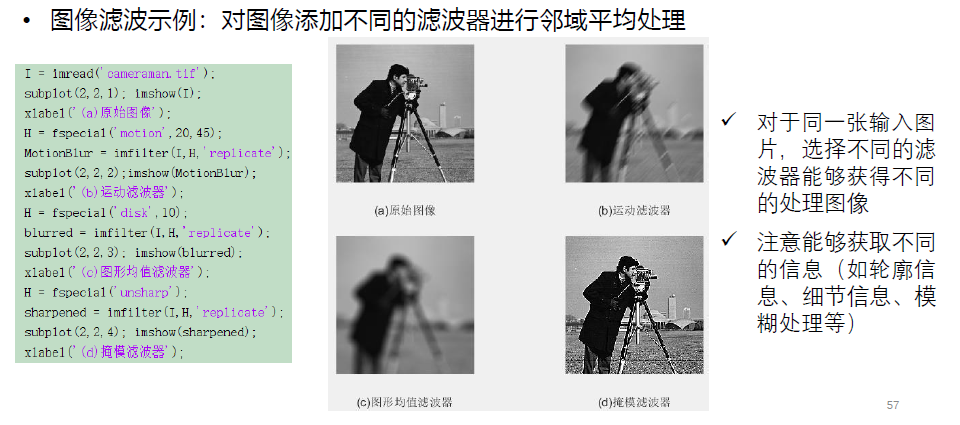

### 图像的其它处理